%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Edit: Idriss Riouak (idriss.riouak@cs.lth.se) 27/03/2020
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## ***Edit Idriss Riouak, 27/03/2020***

## **Sensor Fusion GNSS+INS simulation**

close all
clear

**Loading data from GNSSaidedINS_data.mat and defautl settings**

disp('Loads data');

Loads data


load('GNSSaidedINS_data.mat');
disp('Loads Default settings');

Loads Default settings


settings=get_settings();

**Select sigma_speed**

settings.sigma_speed = 20;

**Select sigma_non_holonomic**

settings.sigma_non_holonomic =20;

**Sensor fusion options:**

if true
    settings.gnss_outage = 'on'; 
else
    settings.gnss_outage = 'off'; 
end
if true
    settings.non_holonomic = 'on'; 
else
    settings.non_holonomic = 'off'; 
end
if true
    settings.speed_aiding = 'on'; 
else
    settings.speed_aiding = 'off'; 
end

**Start simulation:**

 
disp('Runs the GNSS-aided INS')

Runs the GNSS-aided INS


out_data=GPSaidedINS(in_data,settings);

disp('Plot data')

Plot data


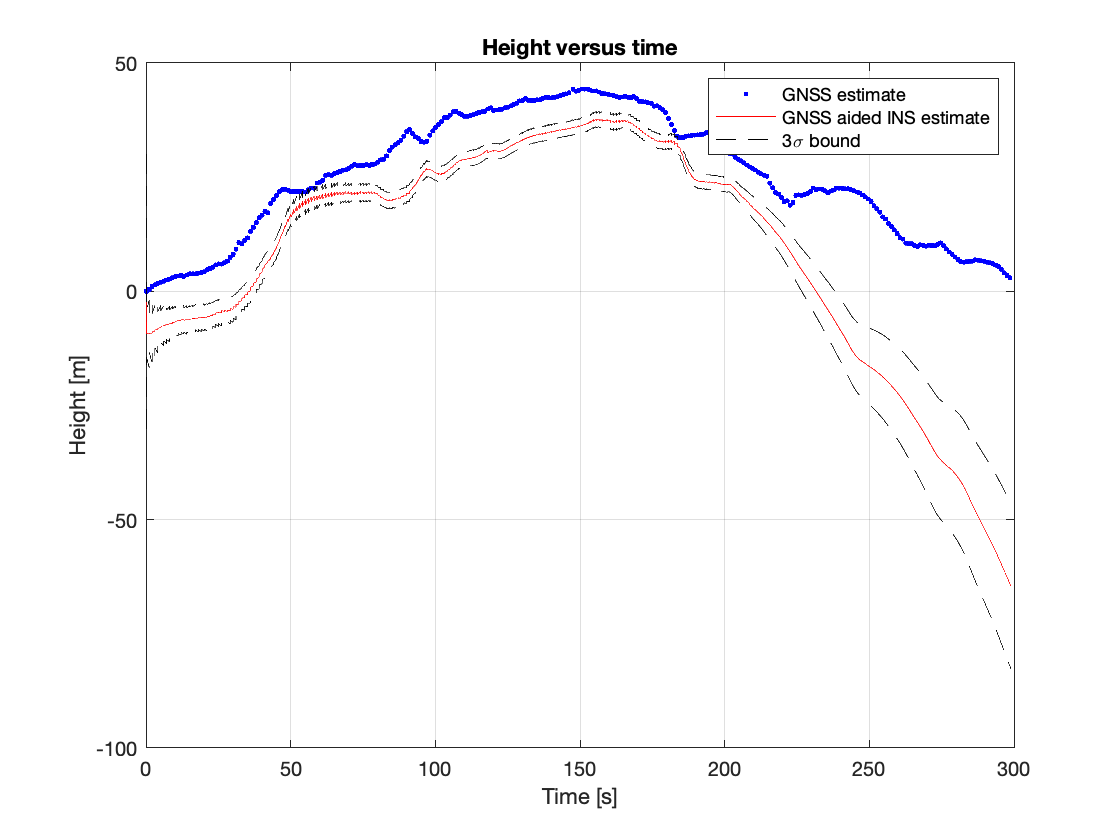

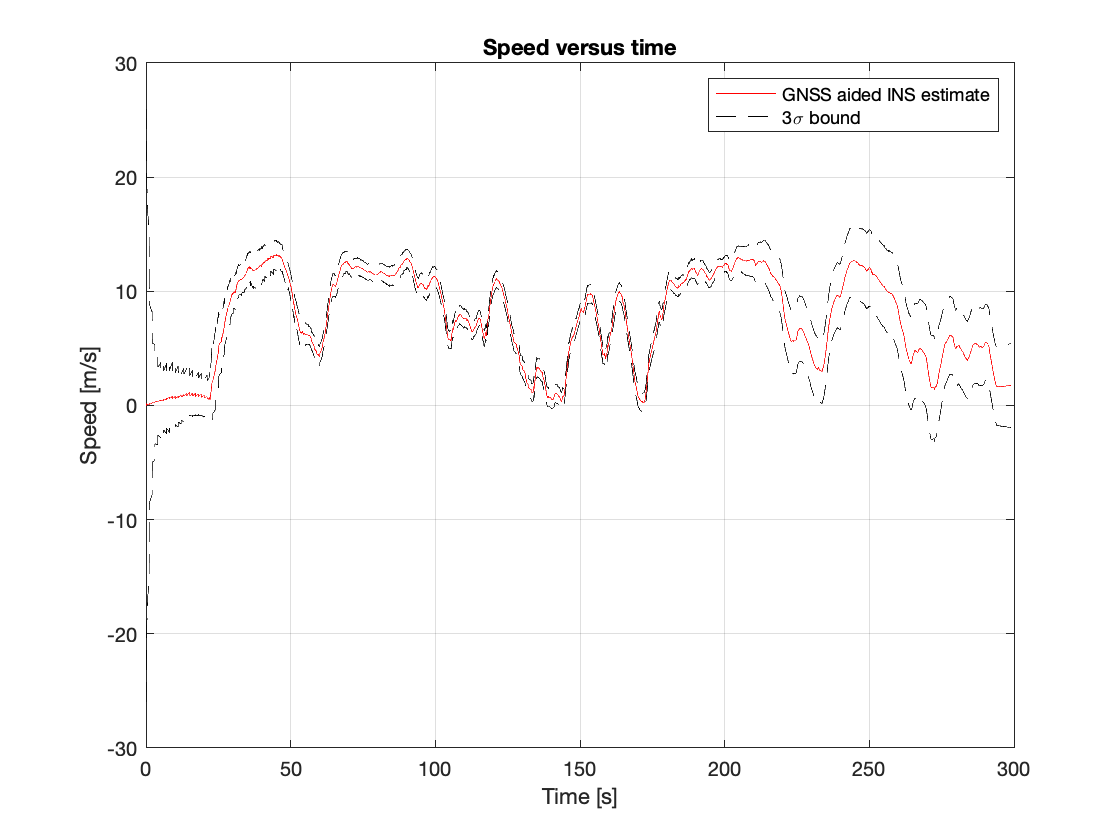

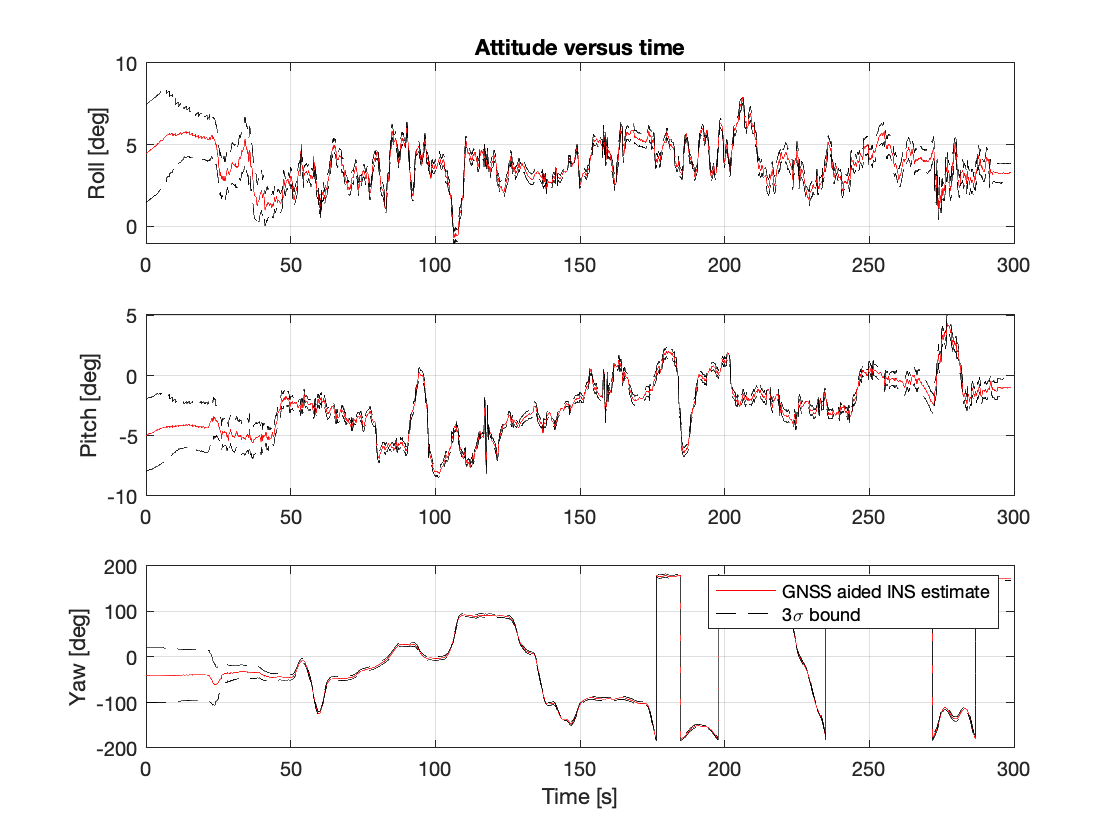

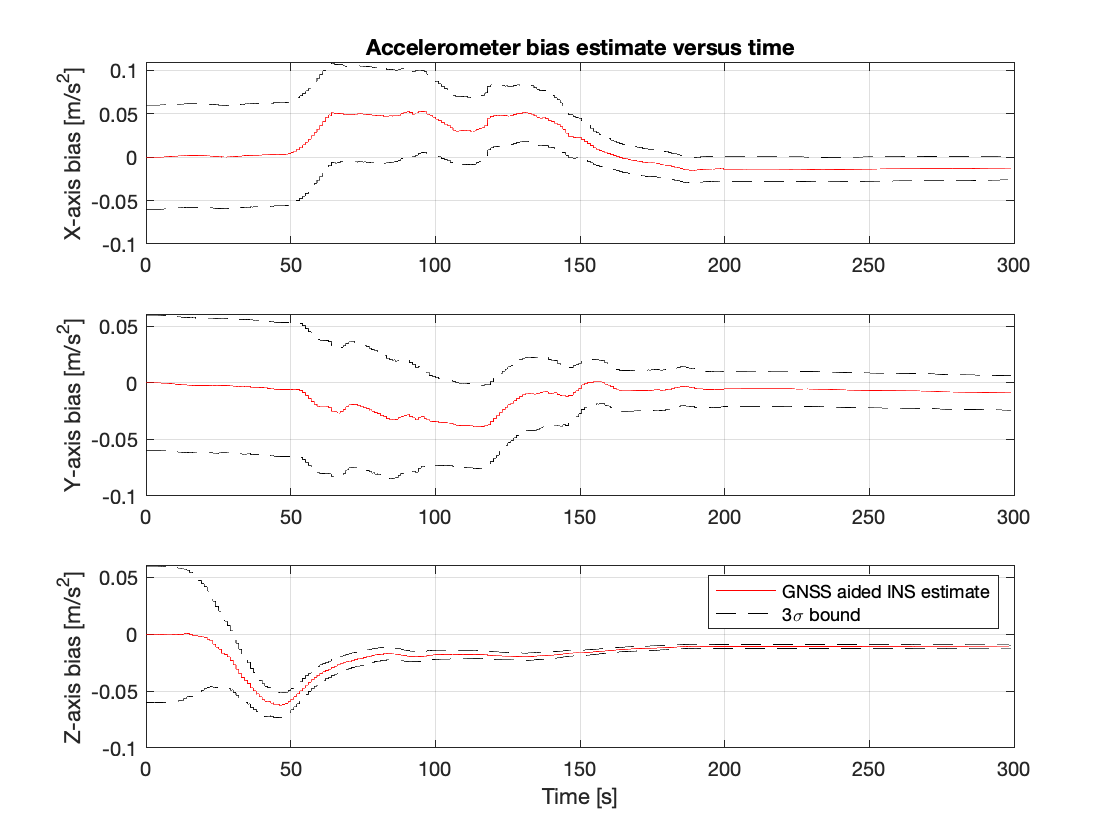

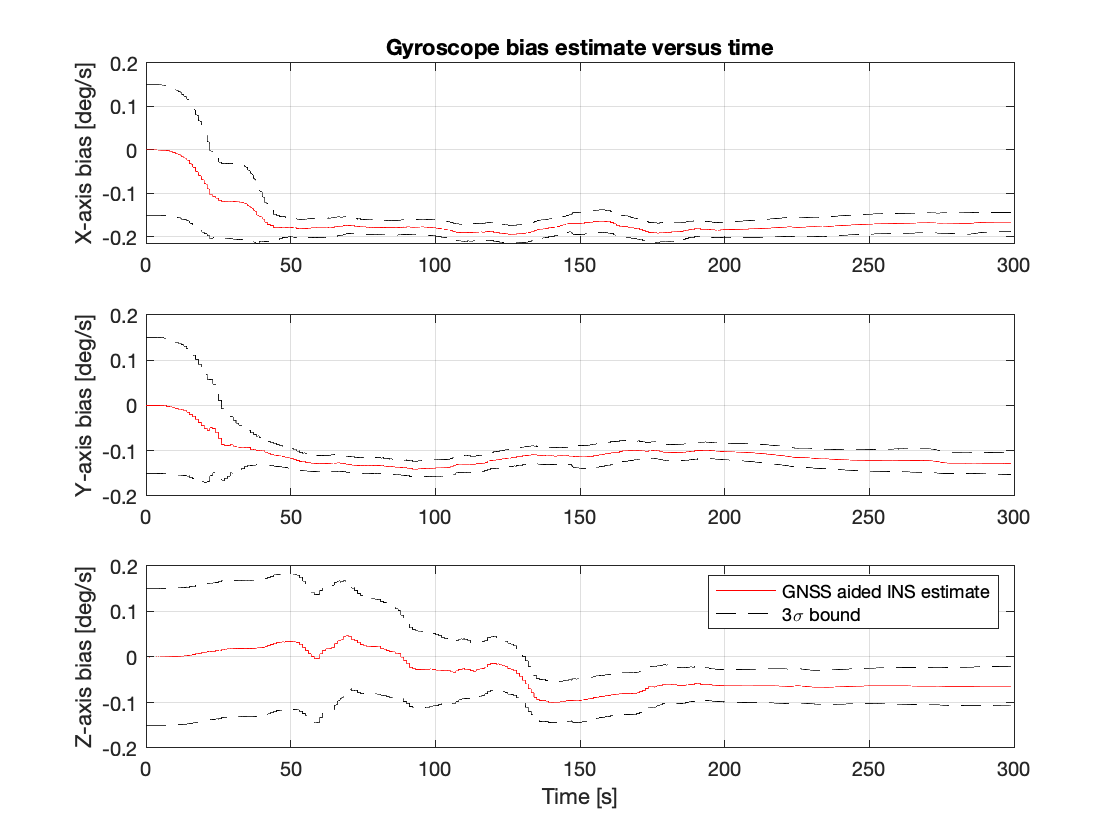

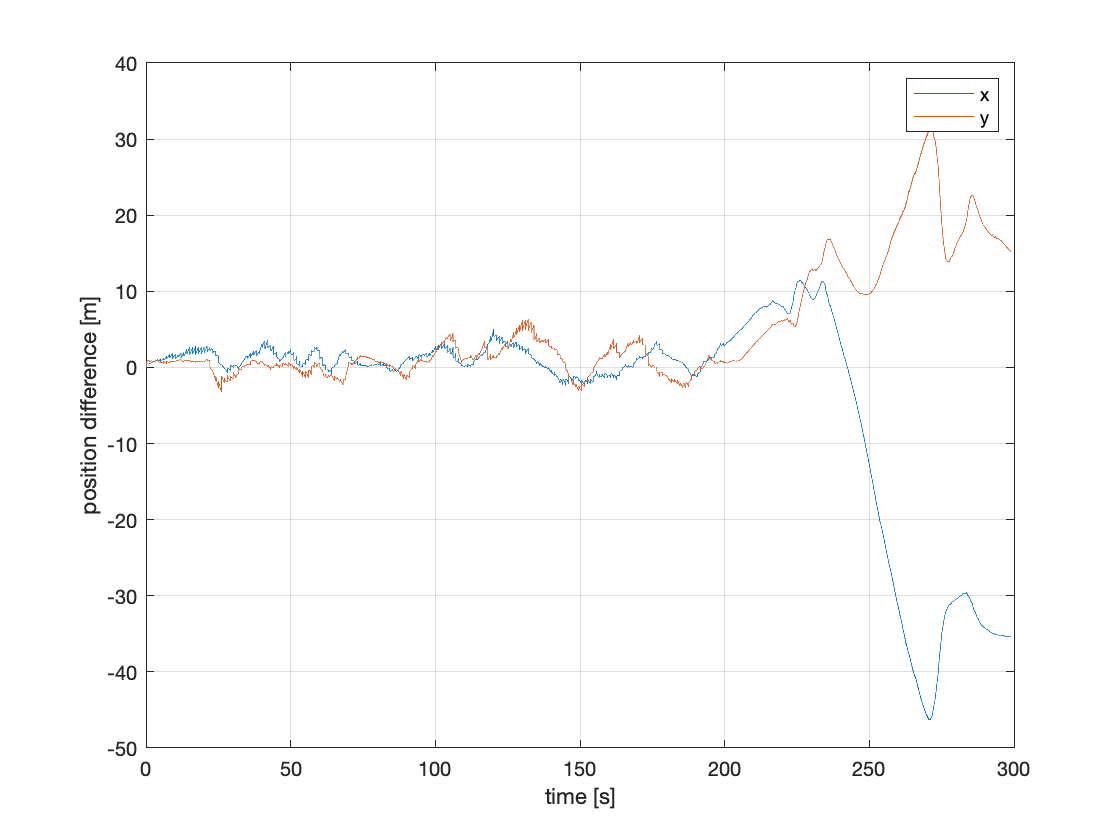

err = plot_data(in_data,out_data,'True');drawnow

fprintf('Error: %.2f.\n', err);

Error: 16.83.


## **Error in different  locations**

close all
clear 

***General Settings:***

polDegree = 3;

gyroBias = 0.01;

gh = [55,51];

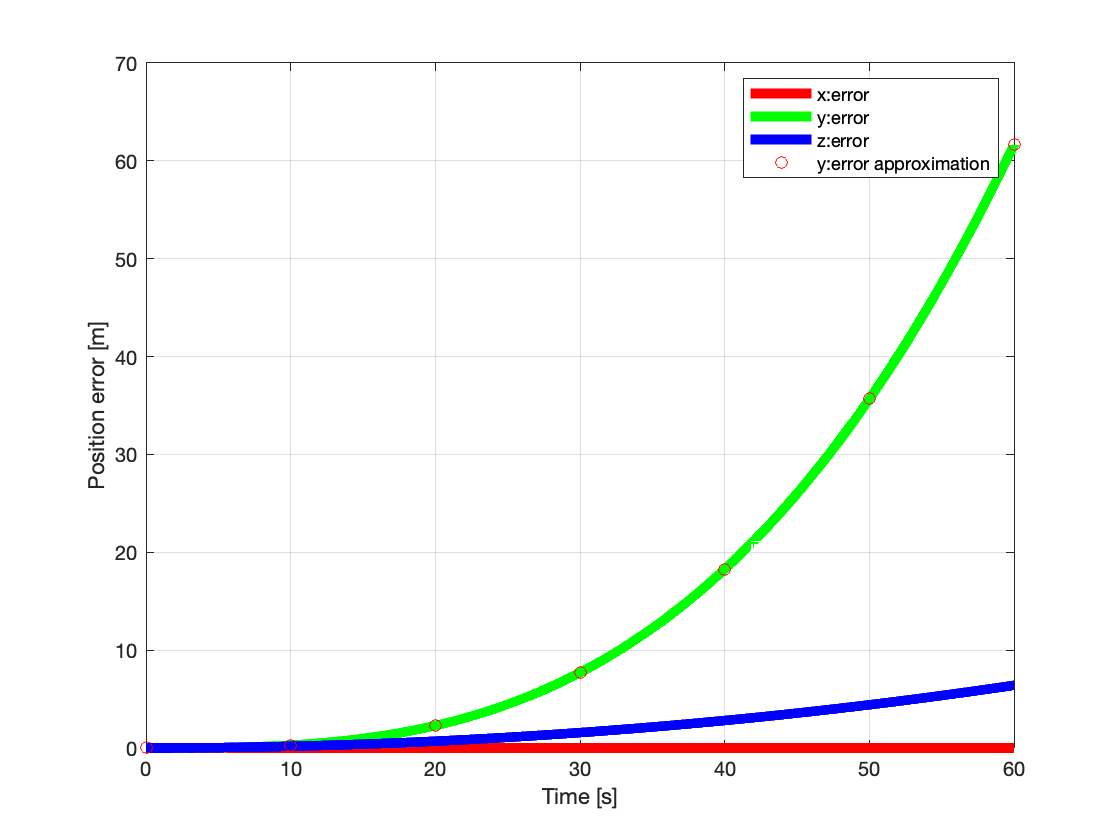


Ts=0.01; %Sampling period of the data
Tmax=60;
t=0:Ts:Tmax; %6001 sampling (100 minutes)
N=length(t);

x=zeros(10,1);
x(end)=1;
accbias = [0;0;0];
gyrobias = [gyroBias*pi/180;0;0];
u = [gravity(gh(1), gh(2)) + accbias; gyrobias];

pos=zeros(3,N);
for n=2:N
   x = Nav_eq(x,u,Ts);
   pos(:,n) = x(1:3);
end

figure(1)
clf
plot(t,pos(1,:)','r',t,pos(2,:)','g',t,pos(3,:)','b', 'LineWidth',5)
grid on
ylabel('Position error [m]')
xlabel('Time [s]')

hold on
yPol = polyfit(t,pos(2,:), polDegree);
plot((0:10:t(end)), polyval(yPol,(0:10:t(end))),'ro')
legend('x:error','y:error','z:error','y:error approximation')

***Error interpolation***

simbolic = poly2sym([yPol]);
disp("P_y(x)=")

P_y(x)=


disp(simbolic)

$$\frac{2633273023360195\,x^{3}}{9223372036854775808}-\frac{2396001577090687\,x^{2}}{590295810358705651712}-\frac{7883777512610987\,x}{2361183241434822606848}+\frac{395595321477871}{36893488147419103232}$$